**Traitement des données électromyographique des sujets (FUNCTIONAL)**

Contexte : analyse des données des tâches motrices **fonctionelles** sur 7 muscles de l'épaule lors de différentes actions : 

- FUNCTIONAL(1) : porter les mains à la bouche

- FUNCTIONAL(2) : toucher le haut de la tête

- FUNCTIONAL(3) : porter les mains le plus haut possible au-dessus de la tête

- FUNCTIONAL(4) : porter les mains le plus haut possible le long de la colonne vertébrale

Traiment des données complet pour les deux épaules et toutes les tâches

clc; clear all;

Paramètres 

% 1) configureStudyParameters : définition des sujets, muscles 
% et de l'assignation des tâches analytics aux tâches fonctionnelles 

% 2) configureEMGParameters : paramètres du traitement de données tels que le filtre,
% la rms et la normalisation du temps 

% 3) initializeDataArrays : initialisation des matrices pour stocker les
% MVC des tâches analytiques, les signaux normalisées et les SNR

Application du traitement de données 

% 1) calculateMVC : calcul la contraction maximale volontaire pour chaque sujet et muscle
% selon la tâche analytic assignée à chaque muscle en prenant la moyenne des cinq valeurs 
% les plus hautes du signal RMS analytic (normalisation par une tâche
% sous-maximale standardisée). Détermine le bruit pour le calcul futur du
% SNR basé sur la calibration au repos des sujets

% 2) processMuscleSide : traitement des données (4 étapes) avec application
% de la normalisation avec une intégration du traitement des artefacts

% 3) processFunctionalTask : applique la fonction précédente pour traiter les données 
% pour une tâche fonctionnelle spécifique

Traitement des artefacts 

% 1) characterizeArtifacts : définis les paramètres de nettoyage des
% artefacts (propose des alternatives basées sur la moyenne, écart-type ou
% médiane du signal)

% 2) createSegmentationFigure : visualisation des artefacts et du nettoyage
% localisé des données

Calcul du rapport signal/bruit 

% 1) calculateSNRWithCal3 : calcule le SNR en se basant sur le signal au repos en
% faisant la moyenne pour estimer le bruit et le signal fonctionnel en
% prenant les 100 plus grandes valeurs moyennées

Calcul du ratio musculaire

% 1) calculateMuscleRatios : application de la formule classique (M1/M2) pour le
% calcul de ratios musculaires 

% 2) calculate_muscle_ratio : calcul le ratio musculaire pour toutes les
% paires de muscles 

% 3) evaluate_muscle_ratio : donne une évaluation du muscle dominant par 
% rapport au ratio calculé

% 4) plotMuscleRatio : visualisation en barplot des ratios musculaire 

Critère de sélection du dentelé antérieur 

% 1) displayMVCForSerra : calcul le MVC du dentelé antérieur, vérifie s'il
% dépasse ou non le suil de 15% (pic) et l'affiche en noir sut les graphiques

Affichage du profil moyen 

% 1) calculateAndDisplayAverageProfile : calcule et affiche les profils moyens

% 2) displayAverageProfile : affiche les profils moyens pour un côté
% spécifique avec les écarts-types

Script principal qui permet de visualiser les données traitées de tous les sujets

Traitement de la population: pre_operation


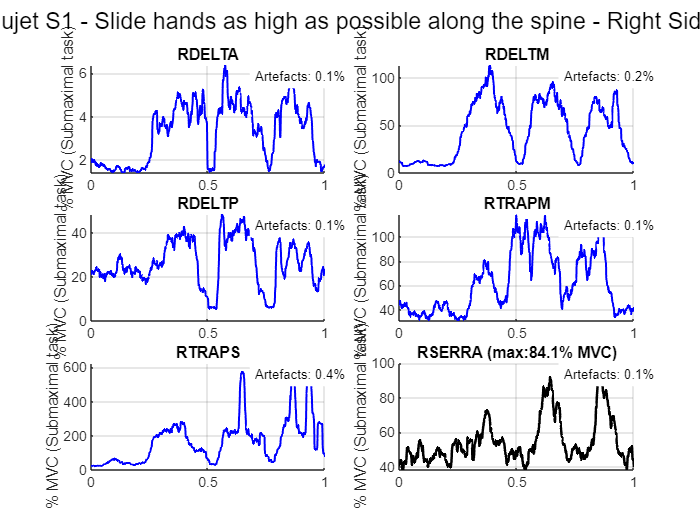

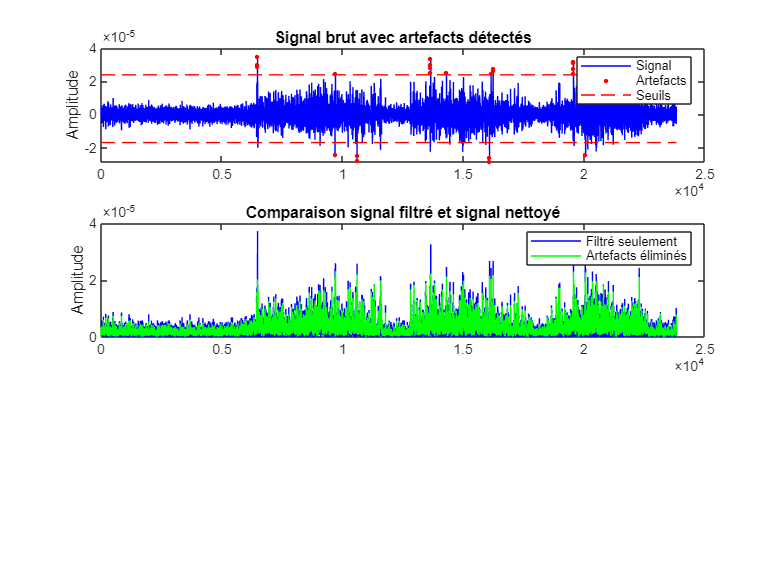

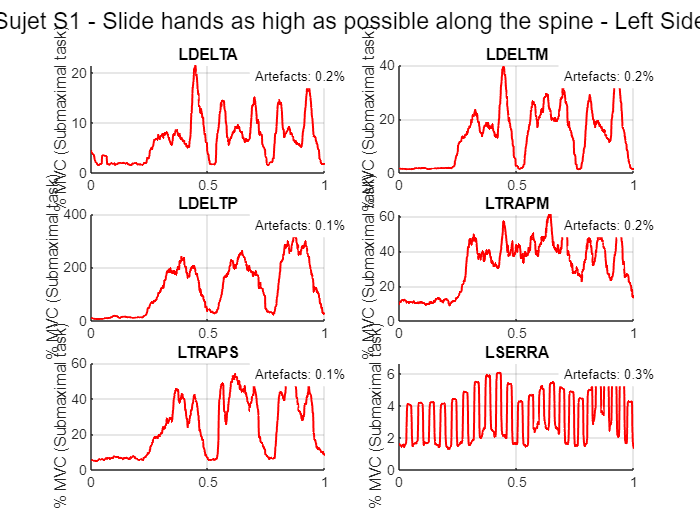

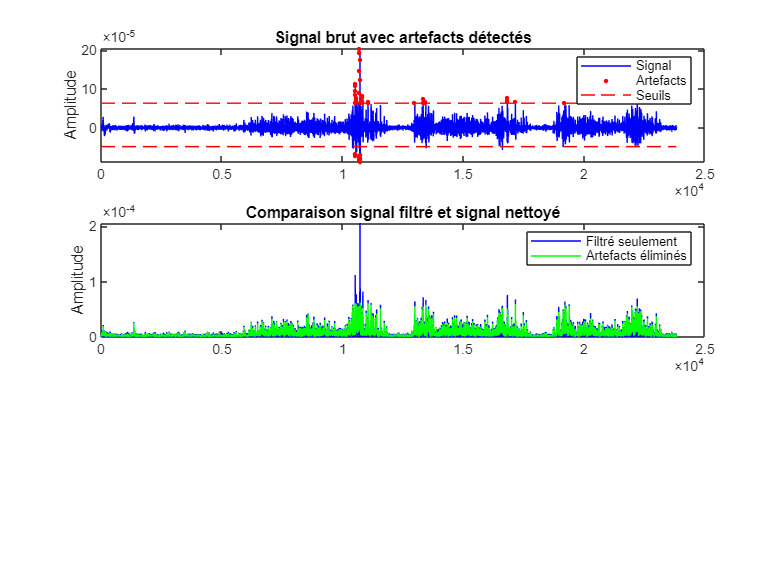

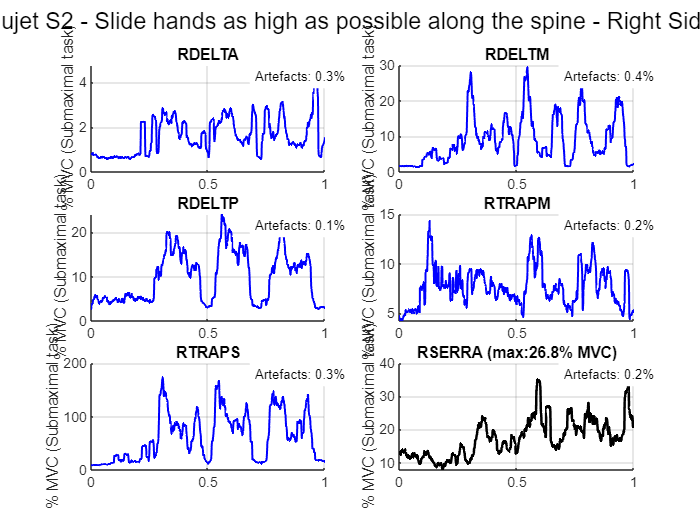

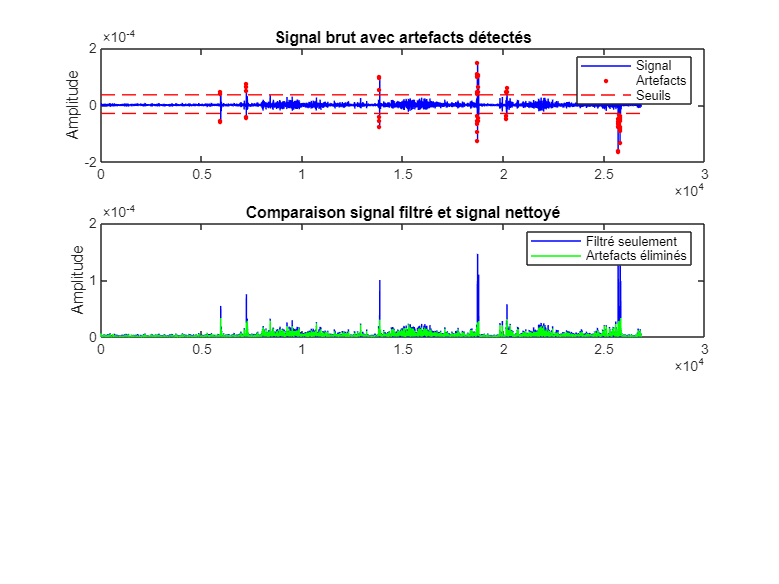

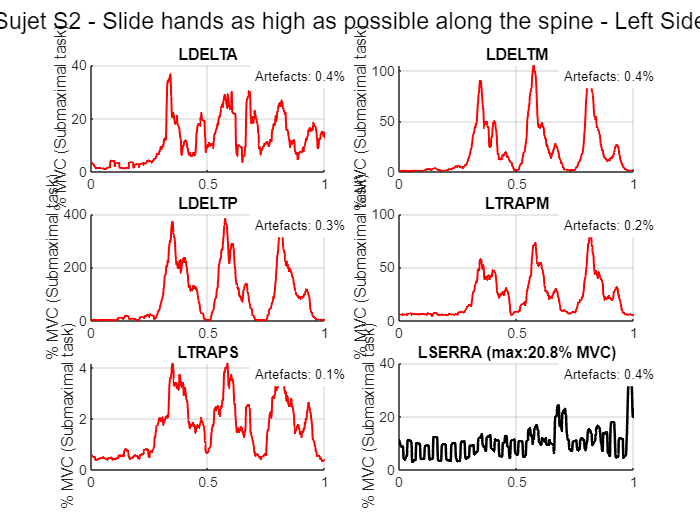

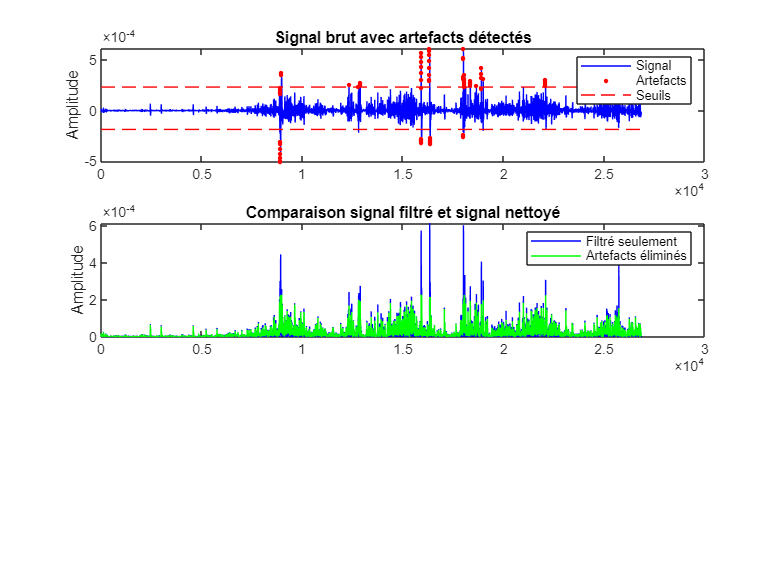


Activation maximale (Muscle         S1             S2             S3             S4             S5             S6             S7             S8             S9             S10            S11            S12            S13            
------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
RSERRA         *84.06*        *26.83*        5.02           10.50          11.82          6.47           *32.16*        *231.82*       *23.96*        9.17           *63.54*        *32.62*        13.39          

Activation maximale (Muscle         S1             S2             S3             S4             S5             S6             S7             S8             S9             S10            S11            S12            S13            
----------------------------------------------------------------------------------------------------------------


===== Création de graphiques moyens avec sélection indépendante des sujets =====
1. Sélectionner des sujets côté droit uniquement
2. Sélectionner des sujets côté gauche uniquement
3. Sélectionner des sujets pour les deux côtés (même sélection)
4. Sélectionner des sujets indépendamment pour chaque côté
5. Sélectionner des sujets indépendamment pour chaque côté et afficher une moyenne combinée
Liste des sujets disponibles pour le côté DROIT :
     1     2     3     4     5     6     7     8     9    10    11    12    13

Liste des sujets disponibles pour le côté GAUCHE :
     1     2     3     4     5     6     7     8     9    10    11    12    13



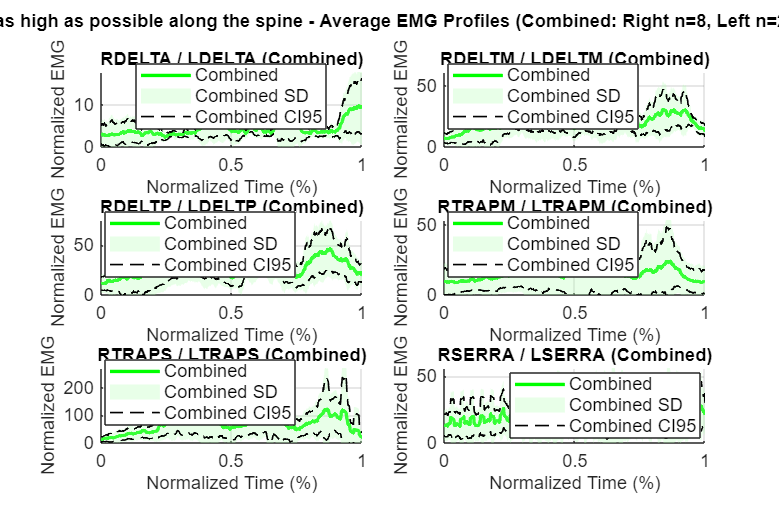


===== Sujets sélectionnés =====
Côté DROIT : [1 2 3 6 7 9 11 12] (n=8)
Côté GAUCHE : [10 13] (n=2)
COMBINÉ : Total (n=10)



===== Calcul du SNR avec sélection des sujets =====
1. Sélectionner des sujets côté droit uniquement
2. Sélectionner des sujets côté gauche uniquement
3. Sélectionner des sujets pour les deux côtés (même sélection)
4. Sélectionner des sujets indépendamment pour chaque côté
5. Sélectionner des sujets indépendamment pour chaque côté et combiner les résultats
Liste des sujets disponibles pour le côté DROIT :
     1     2     3     4     5     6     7     8     9    10    11    12    13

Liste des sujets disponibles pour le côté GAUCHE :
     1     2     3     4     5     6     7     8     9    10    11    12    13


===== Sujets sélectionnés =====
Côté DROIT : [1 2 3 6 7 9 11 12] (n=8)
Côté GAUCHE : [10 13] (n=2)
COMBINÉS pour analyse

Traitement du sujet S1 (Droit) (1/8)
  SNR RDELTA (D): 16.71 dB
  SNR RDELTM (D): 24.40 dB
  SNR RDELTP (D): 25.96 dB
  SNR RTRAPM (D): 15.81 dB
  SNR RTRAPS (D): 38.80 dB
  SNR RSERRA (D): 9.55 dB
Traitement du sujet S2 (Droit) (2/8)
  SNR RDELTA (D): 31.

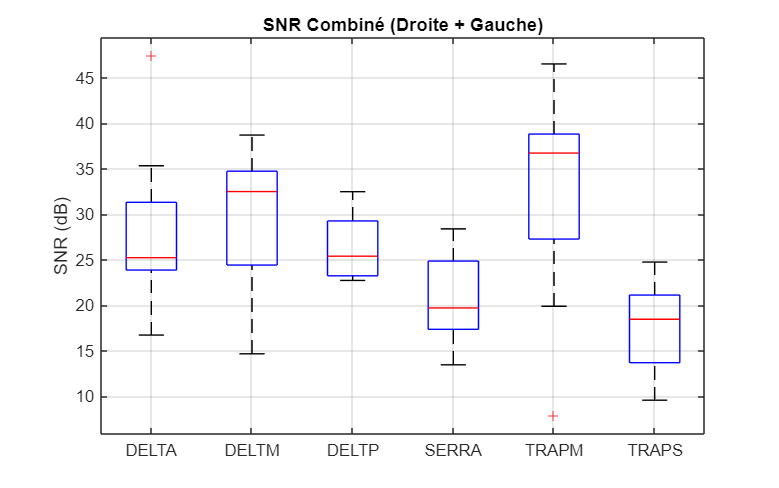

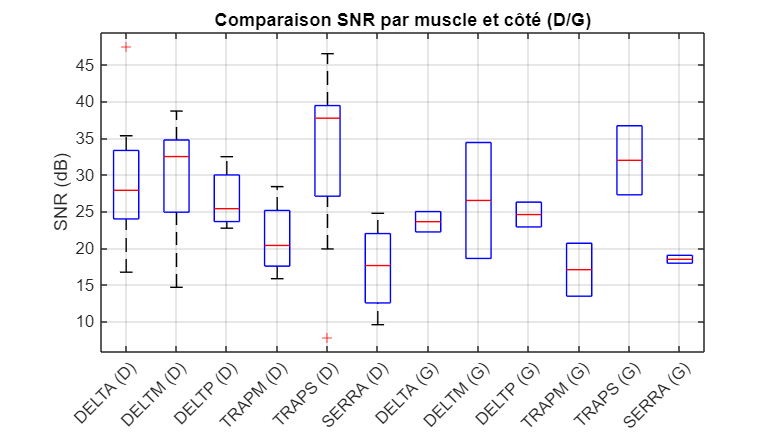

===== MUSCLES DISPONIBLES =====
Muscles côté droit:
    {'RDELTA'}    {'RDELTM'}    {'RDELTP'}    {'RTRAPM'}    {'RTRAPS'}    {'RSERRA'}

Muscles côté gauche:
    {'LDELTA'}    {'LDELTM'}    {'LDELTP'}    {'LTRAPM'}    {'LTRAPS'}    {'LSERRA'}


===== Calcul des ratios musculaires avec sélection des sujets =====
1. Sélectionner des sujets côté droit uniquement
2. Sélectionner des sujets côté gauche uniquement
3. Sélectionner des sujets pour les deux côtés (même sélection)
4. Sélectionner des sujets indépendamment pour chaque côté
5. Sélectionner des sujets indépendamment pour chaque côté et combiner les résultats
Liste des sujets disponibles pour le côté DROIT :
     1     2     3     4     5     6     7     8     9    10    11    12    13

Liste des sujets disponibles pour le côté GAUCHE :
     1     2     3     4     5     6     7     8     9    10    11    12    13


===== Sujets sélectionnés =====
Côté DROIT : [1 2 3 6 7 9 11 12] (n=8)
Côté GAUCHE : [10 13] (n=2)
COMBINÉS pour anal

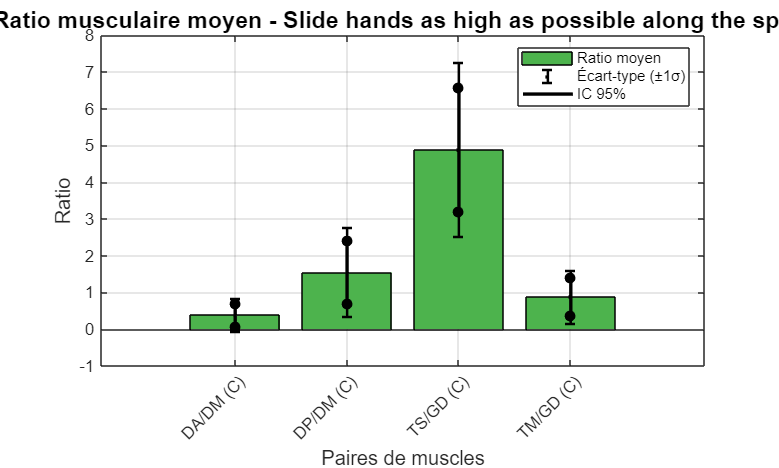

Traitement terminé pour la population: pre_operation



% Choix de la population 
populations = {'pre_operation'}; % asymptomatic / pre_operation / post_operation

% Boucle sur la population sélectionné
for p = 1:length(populations)
    population_type = populations{p};
    fprintf('Traitement de la population: %s\n', population_type);

% Configuration initiale
[subjects, muscles_R, muscles_L, functional_labels, analytic_labels, assigned_analytics, base_path] = configureStudyParameters(population_type);
    
% Paramètres EMG
[fs, b, a, rms_window, num_points, time_normalized] = configureEMGParameters();

% Initialisation des matrices pour stocker les données
nb_subjects = length(subjects);
nb_muscles = length(muscles_R);
[mvc_R, mvc_L, emg_all_subjects_R, emg_all_subjects_L] = initializeDataArrays(nb_subjects, nb_muscles, num_points);
    
% Calcul du MVC et SNR de calibration 3 pour chaque sujet et chaque muscle
[mvc_R, mvc_L] = calculateMVC(subjects, muscles_R, muscles_L, assigned_analytics, b, a, rms_window, nb_subjects, nb_muscles, base_path);

% Sélection d'une tâche fonctionnelle unique
selected_functional = 4; %(1-4)
    
% Traitement des données pour la tâche fonctionnelle sélectionnée
[emg_all_subjects_R, emg_all_subjects_L] = processFunctionalTask(selected_functional, subjects, muscles_R, muscles_L,... 
b, a, rms_window, time_normalized, mvc_R, mvc_L, functional_labels, nb_subjects, nb_muscles, emg_all_subjects_R, emg_all_subjects_L,...
base_path);
    
% Affichage des résultats du SNR avec mise en évidence du SERRA
displayMVCForSERRA(emg_all_subjects_R, emg_all_subjects_L, muscles_R, muscles_L, subjects);
    
% Calcul et affichage des profils moyens
calculateAndDisplayAverageProfiles(time_normalized, emg_all_subjects_R, emg_all_subjects_L,... 
muscles_R, muscles_L, functional_labels, selected_functional, nb_subjects, nb_muscles);

% Calcul du SNR
calculateSNRWithCal3(subjects, muscles_R, muscles_L, selected_functional, base_path);

% Calcul et affichage des ratios musculaires
calculateMuscleRatios(emg_all_subjects_R, emg_all_subjects_L, muscles_R, muscles_L, functional_labels, selected_functional, nb_subjects);

    fprintf('Traitement terminé pour la population: %s\n\n', population_type);
end